# 基于最小二乘的系统辨识

clear;clc

## 1.系统参数和信号设置

m = 5;
c = 20;
k = 100;

T = 20; % 仿真时间
dt = 0.01; % 仿真步长
time = 0 : dt : T; % 仿真时间向量

u = 10*randn(1,length(time))'; % 最大峰值为10N的随机激励 %注意激励比时间的维度少1，实际即u的最后一行没用到
x0 = [0;0]; % 初始位移与速度


## 2.1四阶 Runge-Kutta 方法求解动力学方程

% 自己编写的RungeKutta方法
x_r = zeros(length(time),2); % 存储位移与速度
x_r(1,:) = x0;
for i = 2 : length(time)
    % 四阶 Runge-Kutta 步长法
    % 注意u是当前步长的输入！！
    k1 = [x_r(i-1, 2)                     (-c *  x_r(i-1, 2)                     - k *  x_r(i-1, 1) + 0                 + u(i-1)) / m];
    k2 = [x_r(i-1, 2) + dt * 0.5 * k1(2)  (-c * (x_r(i-1, 2) + dt * 0.5 * k1(2)) - k * (x_r(i-1, 1) + dt * 0.5 * k1(1)) + u(i-1)) / m];
    k3 = [x_r(i-1, 2) + dt * 0.5 * k2(2)  (-c * (x_r(i-1, 2) + dt * 0.5 * k2(2)) - k * (x_r(i-1, 1) + dt * 0.5 * k2(1)) + u(i-1)) / m];
    k4 = [x_r(i-1, 2) + dt *       k3(2)  (-c * (x_r(i-1, 2) + dt *       k3(2)) - k * (x_r(i-1, 1) + dt *       k3(1)) + u(i-1)) / m];

    % 更新状态变量
    x_r(i, :) = x_r(i-1, :) + dt .* (k1 + 2*k2 + 2*k3 + k4) ./ 6;
end
x_r = [x_r [0;diff(x_r(:, 2)) / dt]]; % 利用差分计算加速度


## 2.2传递函数法求解系统响应

A = [0, 1; -k/m, -c/m];
B = [0;1/m];
C = eye(2);
D = 0;
sys = ss(A,B,C,D);
sys_d = c2d(sys,dt);
[A_d, B_d, C_d, D_d] = ssdata(sys_d);
x = zeros(length(time), 2);  % 输出矩阵，存储每个时刻的输出
x(1,:) = x0;
% 仿真离散系统的输出
for i = 2 : length(time)
    % 更新状态
    x(i,:) = (A_d * x(i-1,:)' + B_d * u(i-1))';
end
x = [x [0;diff(x(:, 2)) / dt]]; % 利用差分计算加速度

## 仿真结果绘图

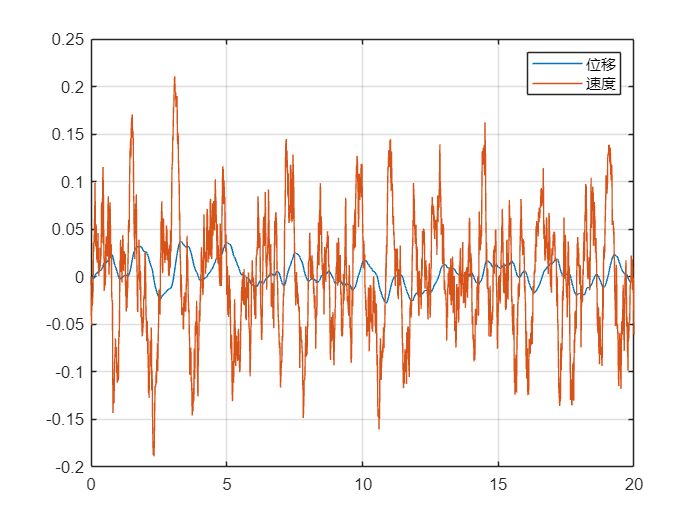

figure
plot(time,x_r(:,1:2))
grid on
legend('位移', '速度')

## 3.最小二乘法拟合

num_samples = 20; % 采样点数
iterations = 5; % 采样轮次
p = zeros(3,iterations);
for iter = 1 : iterations
    % 随机选择20个点进行采样
    indices = randperm(length(time), num_samples);
    x_sample = x_r(indices, 1); % 位移采样
    v_sample = x_r(indices, 2); % 速度采样
    a_sample = x_r(indices, 3); % 加速度采样
    u_sample = u(indices-1); % 激励采样 % !!!采样的u_i-1输入对应输出yi

    % 使用最小二乘法求解系统参数 (m, c, k)
    B = [a_sample v_sample x_sample];
    q = u_sample;
    p(:,iter) = pinv(B) * q; % 或写为 inv(B'*B)*B' 求出的结果等效

    % 检查B矩阵的可逆性
    disp("第"+iter+"轮采样，最小二乘矩阵的条件数为：" + cond(B'*B))
    if cond(B'*B) < 1e8
        disp('矩阵有逆')
    else
        disp('矩阵的可逆性差')
    end
end

第1轮采样，最小二乘矩阵的条件数为：15540.6705


矩阵有逆


第2轮采样，最小二乘矩阵的条件数为：16605.468


矩阵有逆


第3轮采样，最小二乘矩阵的条件数为：21573.4101


矩阵有逆


第4轮采样，最小二乘矩阵的条件数为：26220.0459


矩阵有逆


第5轮采样，最小二乘矩阵的条件数为：12362.9985


矩阵有逆


RMES = sqrt(mean((p - [m;c;k]).^2))

RMES =     0.2923    0.2923    0.2923    0.2923    0.2923


## 4.多自由度模型辨识

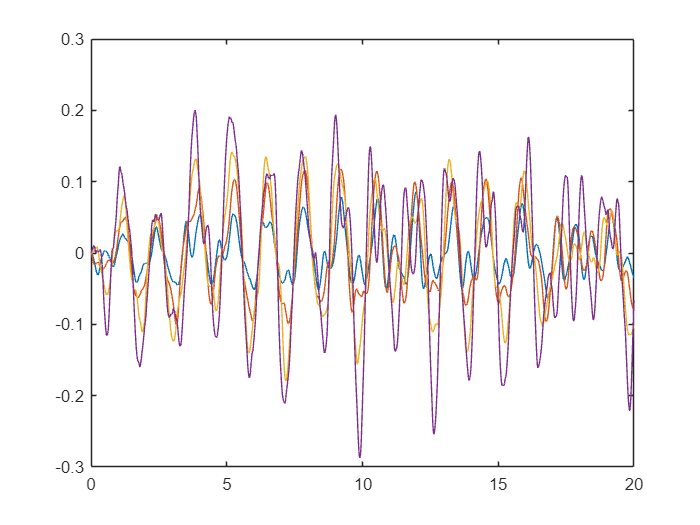

 
mf = [4 3 2 1]';
cf = [4 3 2 1]';
kf = [400 300 200 100]';

% 生成 MLS 信号
f = [mls(length(time)) mls(length(time)) mls(length(time)) mls(length(time))];
f = f(1:length(time),:);
% 将 MLS 信号的范围调整到 [-10, 10]
f = 10 .* (2 .* (f - min(f)) ./ (max(f) - min(f)) - 1);

% 状态空间形式建立
M = eye(length(mf)) .* mf;
C = [cf(1)+cf(2) -cf(2)          0               0;
    -cf(2)         cf(2)+cf(3)  -cf(3)          0;
     0             -cf(3)          cf(3)+cf(4)  -cf(4);
     0              0              -cf(4)          cf(4)];
K = [kf(1)+kf(2) -kf(2)          0               0;
    -kf(2)         kf(2)+kf(3)  -kf(3)          0;
     0             -kf(3)          kf(3)+kf(4)  -kf(4);
     0              0              -kf(4)          kf(4)];
Af = [zeros(length(K)) eye(length(C));
     -inv(M)*K            -inv(M)*C];
Bf = [zeros(length(M));inv(M)];
Cf = eye(size(Af));
Df = 0;
sysf = ss(Af,Bf,Cf,Df);
sysf_d = c2d(sysf,dt);
[Af_d, Bf_d, Cf_d, Df_d] = ssdata(sysf_d);

% 状态空间形式计算
xf = zeros(length(time),length(Af_d))';
uf = zeros(length(time),length(M))';
%uf(1:4,:) = f';
uf(1:4,:) = [10*randn(1,length(time));10*randn(1,length(time));10*randn(1,length(time));10*randn(1,length(time))];
xf0 = [0 0 0 0 0 0 0 0];  % 初始位移与速度
xf(:,1) = xf0;

% 仿真离散系统的输出
for i = 2 : length(time)
    % 更新状态
    xf(:,i) = (Af_d * xf(:,i-1) + Bf_d * uf(:,i-1));
end
tempdiff = xf';
xf = [xf;[0,0,0,0;diff(tempdiff(:,5:8)) / dt]']; % 利用差分计算加速度

plot(time,xf(1:4,:))


% 最小二乘法拟合
num_samples_f = 200; % 采样点数
iterations_f = 5; % 采样轮次
pf = zeros(length(M),3 * length(M),iterations_f);

for iter = 1 : iterations_f
    % 随机选择num_samples_f个点进行采样
    indices_f = randperm(length(time), num_samples_f);
    xf_sample = xf(1:4, indices_f); % 位移采样
    vf_sample = xf(5:8, indices_f); % 速度采样
    af_sample = xf(9:12, indices_f); % 加速度采样
    indices_u = indices_f -1;
    uf_sample = uf(:,indices_u); % 激励采样 % !!!采样的u_i-1输入对应输出yi
    

    % 使用最小二乘法求解系统参数 (m, c, k)
    Bf = [af_sample;vf_sample;xf_sample];
    qf = uf_sample;
    pf(:,:,iter) = qf * pinv(Bf);

    % 检查Bf矩阵的可逆性
    disp("第"+iter+"轮采样，最小二乘矩阵的条件数为：" + cond(Bf'*Bf))
    if cond(Bf'*Bf) < 1e8
        disp('矩阵有逆')
    else
        disp('矩阵的可逆性差')
    end
end

第1轮采样，最小二乘矩阵的条件数为：1.144332530133183e+21


矩阵的可逆性差


第2轮采样，最小二乘矩阵的条件数为：3.447478961787986e+19


矩阵的可逆性差


第3轮采样，最小二乘矩阵的条件数为：5.792616153721534e+19


矩阵的可逆性差


第4轮采样，最小二乘矩阵的条件数为：3.628888714593287e+19


矩阵的可逆性差


第5轮采样，最小二乘矩阵的条件数为：1.884240109875748e+19


矩阵的可逆性差


pf

pf = pf(:,:,1) =

    3.9767    0.0100    0.0000   -0.0000    3.5064   -1.5043    0.0008   -0.0000  700.0000 -300.0000    0.0000    0.0000
    0.0100    2.9834    0.0067    0.0000   -1.5043    2.5053   -1.0026    0.0004 -300.0000  500.0000 -200.0000   -0.0000
    0.0000    0.0067    1.9900    0.0033    0.0008   -1.0026    1.5029   -0.5010    0.0000 -200.0000  300.0000 -100.0000
   -0.0000    0.0000    0.0033    0.9967   -0.0000    0.0004   -0.5010    0.5006   -0.0000   -0.0000 -100.0000  100.0000


pf(:,:,2) =

    3.9767    0.0100    0.0000   -0.0000    3.5064   -1.5043    0.0008   -0.0000  700.0000 -300.0000   -0.0000    0.0000
    0.0100    2.9834    0.0067    0.0000   -1.5043    2.5053   -1.0026    0.0004 -300.0000  500.0000 -200.0000    0.0000
    0.0000    0.0067    1.9900    0.0033    0.0008   -1.0026    1.5029   -0.5010    0.0000 -200.0000  300.0000 -100.0000
   -0.0000    0.0000    0.0033    0.9967   -0.0000    0.0004   -0.5010    0.5006   -0.0000    0.0000 -100.0000  100.0000

% 由于矩阵条件数很大，因此计算的结果不可靠
RMESf = sqrt(mean((pf - [M C K]).^2))

RMESf = RMESf(:,:,1) =

    0.0127    0.0103    0.0062    0.0024    1.9002    1.5375    0.9334    0.3530    0.0000    0.0000    0.0000    0.0000


RMESf(:,:,2) =

    0.0127    0.0103    0.0062    0.0024    1.9002    1.5375    0.9334    0.3530    0.0000    0.0000    0.0000    0.0000


RMESf(:,:,3) =

    0.0127    0.0103    0.0062    0.0024    1.9002    1.5375    0.9334    0.3530    0.0000    0.0000    0.0000    0.0000


RMESf(:,:,4) =

    0.0127    0.0103    0.0062    0.0024    1.9002    1.5375    0.9334    0.3530    0.0000    0.0000    0.0000    0.0000


RMESf(:,:,5) =

    0.0127    0.0103    0.0062    0.0024    1.9002    1.5375    0.9334    0.3530    0.0000    0.0000    0.0000    0.0000


## 5.单自由度系统ARMA自回归滑动模型辨识

 
n_arma = 1; % 回归的参数，默认为位移，但位移不够平稳，可以选取别的

num_samples_a = 200;
% 随机选择num_samples_a个点进行采样
Ba = [x(2:end-1,n_arma) x(1:end-2,n_arma) u(2:end-1)];
qa = x(3:end,n_arma);
indices_a = randperm(length(Ba), num_samples_a);
pa = pinv(Ba(indices_a,:)) * qa(indices_a,:);

% 检查Ba矩阵的可逆性
disp("本轮采样，最小二乘矩阵的条件数为：" + cond(Ba'*Ba))

本轮采样，最小二乘矩阵的条件数为：485563151.7081


if cond(Ba'*Ba) < 1e8
    disp('矩阵有逆')
else
    disp('矩阵的可逆性差')
end

矩阵的可逆性差



-pa

ans =    -1.9808
    0.9832
   -0.0000


xa = zeros(length(time) + 1,1);
for i = 3 : length(time)
    xa(i) = [xa(i-1) xa(i-2) u(i-1)] * pa;
end
xa = xa(2:end);
RMSEa = sqrt(mean((xa - x(:,1)).^2))

RMSEa = 0.0081

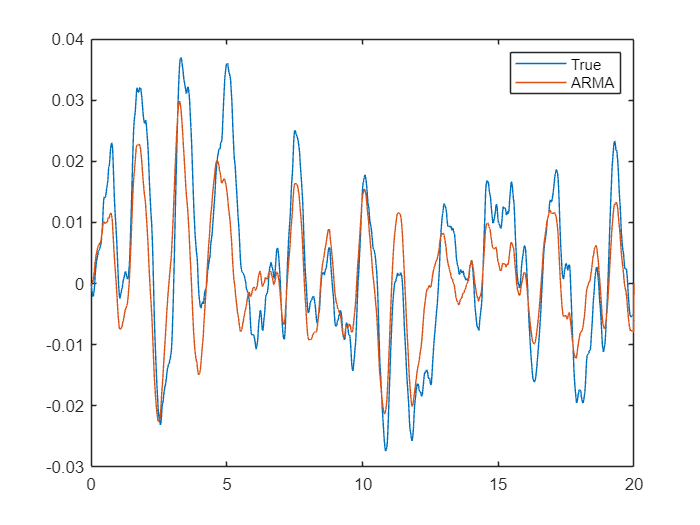

figure
plot(time,[x(:,n_arma),xa])
legend('True','ARMA')

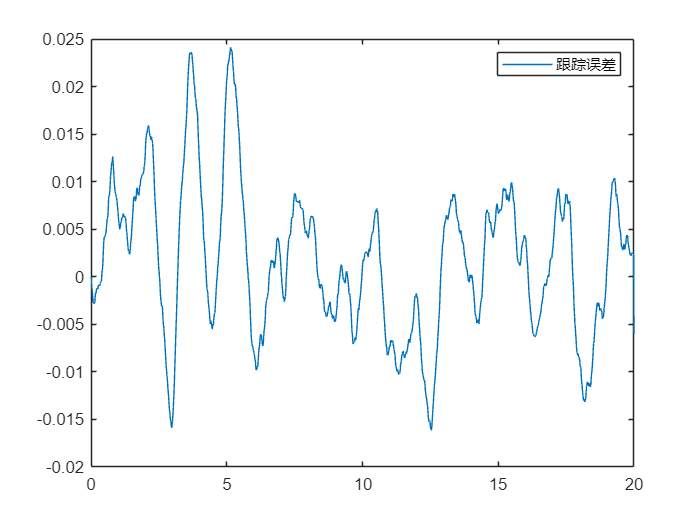

figure
plot(time,x(:,n_arma)-xa)
legend('跟踪误差')

## 6.多自由度系统ARMA自回归滑动模型辨识

 
Y = cell(length(time),1); % 复合元胞矩阵
U = cell(length(time),1); % 复合元胞矩阵
tempxf = xf';
tempuf = uf';
for i = 1 : length(time)
    Y{i,1} = [tempxf(i,3) tempxf(i,4)];
    U{i,1} = [tempuf(i,1) tempuf(i,2)]; 
end

num_samples_af = 200;
% 随机选择num_samples_af个点进行采样
indices_af = randperm(length(Ba), num_samples_af);
indices_af = 1 : length(Ba);
Ba_f = [Y(2:end-1,:) Y(1:end-2,:) U(2:end-1,:) U(1:end-2,:)];
qa_f = Y(3:end,:);
Ba_f = cell2mat(Ba_f(indices_af,:));
qa_f = cell2mat(qa_f(indices_af,:));

% 检查Ba矩阵的可逆性
disp("本轮采样，最小二乘矩阵的条件数为：" + cond(Ba_f'*Ba_f))

本轮采样，最小二乘矩阵的条件数为：22661551.5514


if cond(Ba_f'*Ba_f) < 1e8
    disp('矩阵有逆')
else
    disp('矩阵的可逆性差,结果可能并不可靠')
end

矩阵有逆



pa_f = pinv(Ba_f) * qa_f;
mat2cell(pa_f,[2,2,2,2])

ans = 4×1 cell 数组
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {2×2 double}


## 疑惑与检验

cond(pa_f) 

ans = 1.0112

qa_fs = Ba_f * pa_f; 
RMSEa = sqrt(mean((qa_fs - qa_f).^2)) % 反算的qa_fs误差

RMSEa = 1.0e-03 *

    0.4185    0.7153


Ba_fs = qa_f * pinv(pa_f);
RMSEcs = sqrt(mean((Ba_fs - Ba_f).^2)) % 为什么这个U项误差这么大

RMSEcs =     0.0436    0.0612    0.0874    0.1221   10.3925   10.0183   10.3944   10.0176


figure
Ba_fsp3 = [0;Ba_fs(1,3);Ba_fs(:,1)]; % 从反算的B矩阵提取出位移三
RMSEaf3 = sqrt(mean((Ba_fsp3 - xf(3,:)).^2))

RMSEaf3 =     0.0294    0.0294    0.0294    0.0294    0.0294    0.0294    0.0294    0.0295    0.0295    0.0296    0.0296    0.0297    0.0298    0.0299    0.0299    0.0300    0.0302    0.0305    0.0309    0.0311    0.0311    0.0310    0.0307    0.0305    0.0303    0.0300    0.0296    0.0294    0.0293    0.0295    0.0299    0.0306    0.0315    0.0325    0.0336    0.0349    0.0363    0.0377    0.0389    0.0399    0.0408    0.0417    0.0427    0.0438    0.0451    0.0466    0.0486    0.0507    0.0525    0.0541


plot(time,[xf(:,3),Ba_fsp3])

错误使用 horzcat
要串联的数组的维度不一致。

legend('True','ARMA')
title('第 3 层隔振系统位移响应')
figure
Ba_fsp4 = [0;Ba_fs(1,4);Ba_fs(:,2)]; % 从反算的B矩阵提取出位移四
RMSEaf4 = sqrt(mean((Ba_fsp4 - xf(:,3)).^2))
plot(time,[xf(:,4),Ba_fsp4])
legend('True','ARMA')
title('第 4 层隔振系统位移响应')

## 未能解决的错误


xa_f = cell(length(time)+1,1);
for i = 1 : length(time)+1
    xa_f{i} = zeros(1,2);
end
for i = 3 : length(time)
    xa_f{i} = [cell2mat(xa_f(i-1)) cell2mat(xa_f(i-2)) cell2mat(U(i-1)) cell2mat(U(i-2))] * pa_f;
end
xa_f = xa_f(2:end)

figure
xa_fmat = cell2mat(xa_f);
plot(time,[xf(:,3),xa_fmat(:,1)])
legend('True','ARMA')
figure
plot(time,[xf(:,4),xa_fmat(:,2)])
legend('True','ARMA')